# NB-IoT simulation

## ofdm parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=28;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz


## simulation parameters

dataLength=numSC*numSym*2;
randomData=true;
nLoops=8;
filtersOn=false;%still have to toggle
maxSNR=22;

## transmission


%base message
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     1
     0
     1
     1
     1
     1
     1
     0
     0



%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      1
     1
     3
     3
     0
     0
     3
     0
     3
     0


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =   -0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i


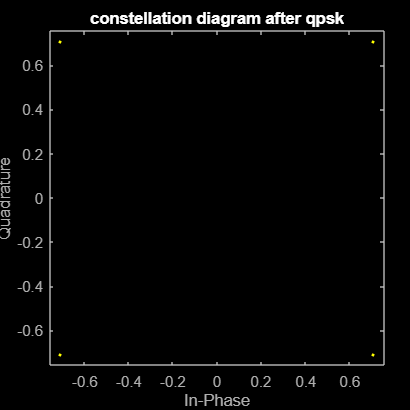

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

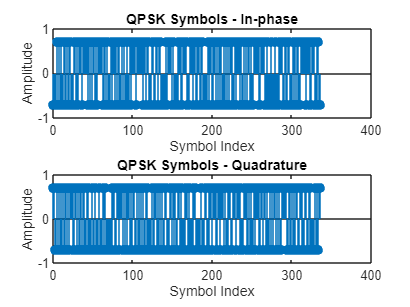


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


% numSC=12;% # subcarriers
% numSym=21;% # ofdm symbols
% SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
t = (0:SPS-1) / samplingRate; %time vector
ofdmSignal = zeros(1, numSym * SPS);
cpLen=round(SPS/4);%cyclic prefix length


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =   -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i
  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.707

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.3536 + 0.1179i  -0.1179 - 0.1179i  -0.3536 + 0.2357i  -0.1179 + 0.0000i   0.1179 + 0.2357i   0.1179 - 0.1179i   0.2357 + 0.2357i  -0.1179 - 0.2357i   0.2357 + 0.1179i  -0.1179 + 0.0000i   0.0000 - 0.1179i   0.1179 - 0.2357i   0.0000 + 0.0000i   0.0000 + 0.1179i   0.0000 - 0.1179i  -0.1179 - 0.2357i  -0.3536 + 0.0000i   0.1179 + 0.3536i   0.0000 + 0.0000i   0.0000 + 0.2357i  -0.1179 - 0.2357i   0.2357 + 0.0000i   0.1179 - 0.2357i  -0.1179 + 0.1179i   0.4714 + 0.3536i   0.0000 + 0.0000i   0.4714 + 0.0000i  -0.1179 - 0.1179i
  -0.0589 + 0.2199i  -0.3651 - 0.1610i  -0.2357 - 0.1179i   0.2041 + 0.0000i  -0.2946 + 0.1021i   0.1768 - 0.2199i  -0.0589 - 0.2515i  -0.0158 + 0.1768i  -0.0863 + 0.2041i   0.0158 - 0.1768i  -0.2788 + 0.2473i  -0.2199 - 0.4988i   0.1610 - 0.3967i  -0.2199 + 0.0589i   0.1021 + 0.0273i  -0.3062 - 0.0273i  -0.3220 + 0.2041i   0.1610 - 0.0747i  -0.3062 - 0.0273i  -0.0273 + 0.2199i   0.4240 + 0.0589i  -0.2630 + 0.1021i   0.2788 + 0.1610i  -0.0905 + 0.1021i  -0.0

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.3536 + 0.1179i  -0.1179 - 0.1179i  -0.3536 + 0.2357i  -0.1179 + 0.0000i   0.1179 + 0.2357i   0.1179 - 0.1179i   0.2357 + 0.2357i  -0.1179 - 0.2357i   0.2357 + 0.1179i  -0.1179 + 0.0000i   0.0000 - 0.1179i   0.1179 - 0.2357i   0.0000 + 0.0000i   0.0000 + 0.1179i   0.0000 - 0.1179i  -0.1179 - 0.2357i  -0.3536 + 0.0000i   0.1179 + 0.3536i   0.0000 + 0.0000i   0.0000 + 0.2357i  -0.1179 - 0.2357i   0.2357 + 0.0000i   0.1179 - 0.2357i  -0.1179 + 0.1179i   0.4714 + 0.3536i   0.0000 + 0.0000i   0.4714 + 0.0000i  -0.1179 - 0.1179i
  -0.0589 + 0.2199i  -0.3651 - 0.1610i  -0.2357 - 0.1179i   0.2041 + 0.0000i  -0.2946 + 0.1021i   0.1768 - 0.2199i  -0.0589 - 0.2515i  -0.0158 + 0.1768i  -0.0863 + 0.2041i   0.0158 - 0.1768i  -0.2788 + 0.2473i  -0.2199 - 0.4988i   0.1610 - 0.3967i  -0.2199 + 0.0589i   0.1021 + 0.0273i  -0.3062 - 0.0273i  -0.3220 + 0.2041i   0.1610 - 0.0747i  -0.3062 - 0.0273i  -0.0273 + 0.2199i   0.4240 + 0.0589i  -0.2630 + 0.1021i   0.2788 + 0.1610i  -0.


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.3536 + 0.1179i
  -0.0589 + 0.2199i
  -0.2199 - 0.0273i
  -0.2357 + 0.0000i
  -0.3062 - 0.0589i
  -0.0589 + 0.0158i
  -0.1179 + 0.3536i
  -0.2630 + 0.1021i
   0.3062 - 0.0589i
  -0.2357 - 0.2357i


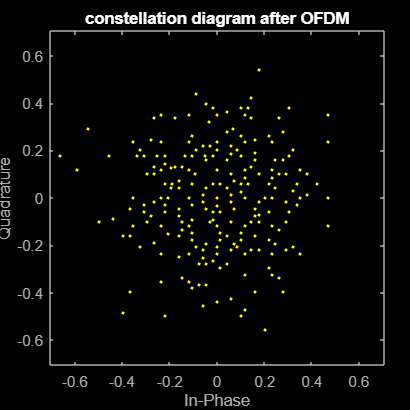

% plot ofdm signal
figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

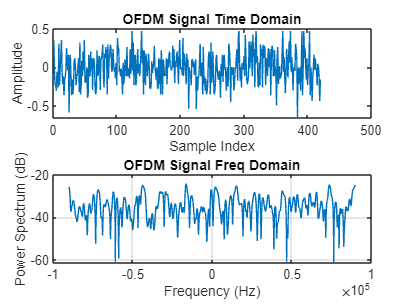


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

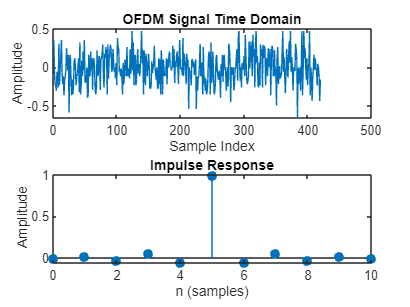

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

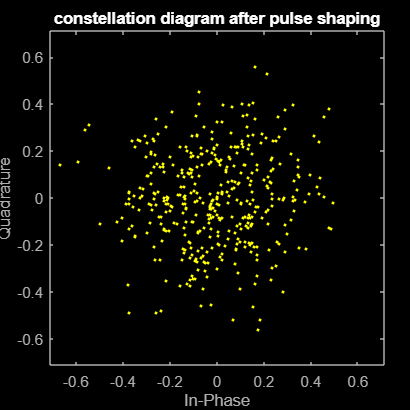

if filtersOn
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');

end

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

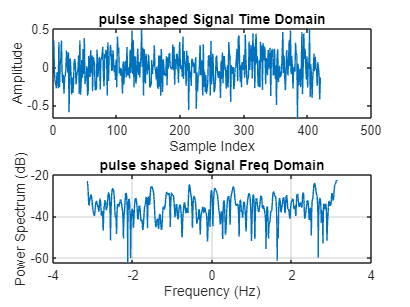


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

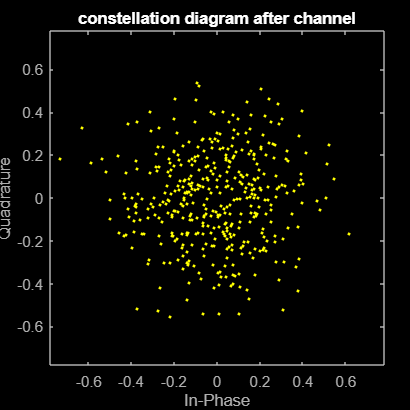

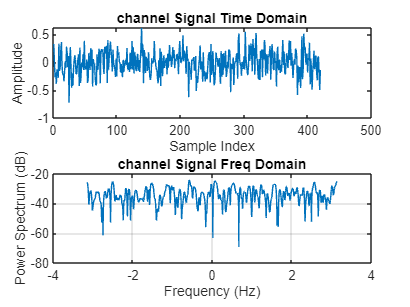

for counter=1:nLoops
%check filters, error rate is te hoog?

SNR=20-(nLoops-counter);
% rxSignal=awgn(txSignalShaped,SNR);

rxSignal=awgn(txSignalUpsampled,SNR);
% rxSignal=txSignalShaped;

if counter==nLoops %only plot in last loop
    % Plot the time domain signal after channel
    figure
    scatterplot(rxSignal)
    title('constellation diagram after channel');
    
    % Plot the time domain signal
    figure;
    subplot(2,1,1);
    plot(real(rxSignal));
    title('channel Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(rxSignal);
    subplot(2,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('channel Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
if filtersOn
    rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
else
    rxSignalFiltered = rxSignal;

end
matchedFilter = rcosdesign(rolloff, span, L);
rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
rxSignalFiltered

rxSignalFiltered =    0.5201 + 0.0691i
  -0.1331 + 0.3027i
  -0.3607 - 0.0785i
  -0.3272 + 0.0092i
  -0.2373 - 0.1700i
  -0.1098 - 0.1370i
   0.0821 + 0.2808i
  -0.4679 + 0.0931i
   0.4664 + 0.0411i
  -0.0550 - 0.4152i


rxSignalFiltered =    0.4946 + 0.1334i
  -0.0622 + 0.2153i
   0.1166 - 0.3032i
  -0.4637 - 0.0094i
  -0.1800 - 0.2978i
  -0.2879 + 0.0528i
   0.1425 + 0.5393i
  -0.2389 + 0.1873i
   0.2258 + 0.1216i
  -0.1739 - 0.3589i


rxSignalFiltered =    0.2448 + 0.3708i
  -0.1999 + 0.1867i
  -0.1677 + 0.0437i
  -0.1503 + 0.0819i
  -0.1189 - 0.0639i
  -0.3201 - 0.0856i
  -0.0107 + 0.4814i
  -0.1616 + 0.0940i
   0.5057 - 0.0279i
  -0.2885 - 0.3746i


rxSignalFiltered =    0.2026 + 0.1035i
  -0.1921 + 0.1915i
  -0.4004 - 0.0262i
  -0.1057 - 0.0062i
  -0.1621 - 0.0124i
  -0.0701 + 0.0408i
  -0.0213 + 0.3412i
  -0.2864 + 0.0440i
   0.3422 - 0.0963i
  -0.2720 - 0.2186i


rxSignalFiltered =    0.4585 + 0.1435i
  -0.1513 + 0.2731i
  -0.2412 + 0.0441i
  -0.2022 + 0.0378i
  -0.1891 - 0.0796i
   0.0471 - 0.0734i
  -0.2520 + 0.1642i
  -0.1654 + 0.0622i
   0.4171 - 0.0882i
  -0.2186 - 0.3151i


rxSignalFiltered =    0.3283 + 0.1582i
   0.0391 + 0.2871i
  -0.1555 - 0.0985i
  -0.0607 + 0.0103i
  -0.1571 + 0.0699i
  -0.1999 - 0.1391i
  -0.1388 + 0.4984i
  -0.2863 + 0.1143i
   0.3161 - 0.0842i
  -0.3211 - 0.3169i


rxSignalFiltered =    0.3379 + 0.0081i
   0.0271 + 0.2905i
  -0.2320 + 0.1023i
  -0.0689 - 0.0456i
  -0.2653 - 0.0576i
  -0.0633 - 0.0584i
  -0.0303 + 0.3159i
  -0.3157 + 0.0338i
   0.2056 + 0.1672i
  -0.2357 - 0.3368i


rxSignalFiltered =    0.3115 + 0.1978i
  -0.0226 + 0.2247i
  -0.2574 - 0.0943i
  -0.1589 - 0.0523i
  -0.3643 - 0.1048i
  -0.1213 + 0.0622i
  -0.1612 + 0.2953i
  -0.2810 + 0.0925i
   0.3388 - 0.0954i
  -0.1801 - 0.2381i


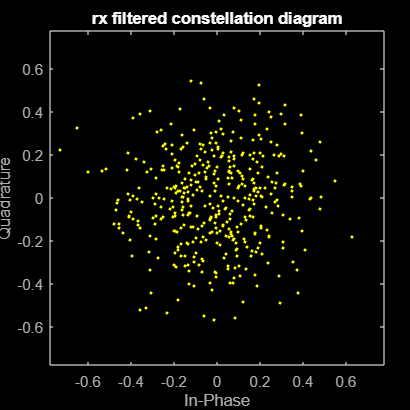


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);
if counter==nLoops
    figure;
    scatterplot(rxSignalFiltered);
    title('rx filtered constellation diagram');
end


%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignal, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =    0.5308 + 0.0937i  -0.4067 + 0.2308i  -0.2065 + 0.1455i  -0.1853 + 0.1041i   0.1203 - 0.0008i   0.1388 - 0.0909i   0.2020 + 0.3156i   0.1104 - 0.6695i   0.2412 + 0.1953i  -0.1654 - 0.0217i   0.1269 - 0.2879i   0.6593 - 0.3859i  -0.2166 - 0.3522i  -0.0143 + 0.4644i  -0.0711 + 0.0501i  -0.1598 - 0.1191i  -0.2687 + 0.0756i   0.1985 + 0.2852i   0.0643 + 0.0101i  -0.1841 + 0.3683i  -0.3189 - 0.1731i   0.4406 + 0.1080i   0.2815 - 0.5396i  -0.1349 + 0.1930i   0.2503 + 0.2931i   0.0692 - 0.0966i   0.4578 - 0.2234i   0.0136 - 0.0573i
  -0.1186 + 0.3054i  -0.4025 - 0.3076i  -0.4012 - 0.3178i   0.0390 - 0.1483i  -0.5874 - 0.0267i  -0.0837 - 0.2243i  -0.2232 + 0.0614i  -0.1600 + 0.0945i  -0.0462 + 0.2206i   0.0021 - 0.2113i  -0.2582 + 0.6948i  -0.1014 - 0.2327i   0.2794 - 0.3827i  -0.3914 + 0.1288i   0.1489 + 0.0843i  -0.4076 - 0.1011i  -0.3054 - 0.1618i   0.1198 - 0.0806i  -0.0715 - 0.1733i  -0.0055 + 0.1335i   0.3300 - 0.1229i  -0.3149 - 0.1229i   0.4072 + 0.1248i   0.1132 + 

rxSymbolsWithCP =    0.4823 + 0.1664i  -0.4034 - 0.2873i  -0.1770 + 0.3217i  -0.1088 - 0.0922i   0.2002 + 0.3819i   0.2013 - 0.0311i   0.0900 + 0.1541i   0.0598 - 0.5435i   0.3455 + 0.0162i   0.0095 + 0.0141i  -0.0405 - 0.1239i   0.3095 - 0.2044i  -0.0169 + 0.1215i  -0.1962 - 0.0342i   0.0926 - 0.5282i  -0.0403 - 0.1289i  -0.4619 - 0.0034i   0.1746 + 0.3682i  -0.2968 - 0.1057i   0.2252 + 0.1215i   0.1472 - 0.2624i   0.3356 + 0.0062i   0.1835 - 0.2102i  -0.3243 + 0.1550i   0.3965 + 0.3250i   0.0820 + 0.0987i   0.3340 - 0.0600i  -0.0114 + 0.0523i
  -0.0110 + 0.2032i  -0.4923 - 0.2799i  -0.2907 + 0.0523i   0.2486 - 0.0080i  -0.3493 + 0.1827i   0.0417 + 0.0737i  -0.0538 - 0.2728i   0.1090 - 0.0815i   0.0717 + 0.2909i   0.1248 - 0.0948i  -0.5464 + 0.3027i  -0.1355 - 0.6853i  -0.0944 - 0.3521i  -0.2658 + 0.0208i   0.2834 + 0.0911i  -0.3809 + 0.0351i  -0.4140 + 0.3122i   0.2850 - 0.5102i  -0.2218 + 0.1809i  -0.0676 + 0.2112i   0.4675 + 0.2147i  -0.1803 + 0.1120i   0.1737 + 0.1988i  -0.1612 + 

rxSymbolsWithCP =    0.2415 + 0.3892i   0.0078 + 0.0138i  -0.4678 + 0.3679i  -0.1153 - 0.1113i   0.1655 + 0.2476i  -0.0836 - 0.1972i   0.4903 + 0.1155i  -0.0635 - 0.1335i   0.3290 + 0.0906i  -0.2197 + 0.0903i  -0.0617 - 0.0876i   0.0691 - 0.0058i  -0.1071 - 0.0209i  -0.0562 - 0.0465i  -0.1674 - 0.2456i  -0.1471 - 0.4787i  -0.4767 - 0.0154i   0.0511 + 0.3211i   0.0389 - 0.1580i  -0.0187 + 0.2128i   0.0651 - 0.2669i   0.3119 - 0.1224i   0.1107 - 0.2518i  -0.0856 + 0.0321i   0.6926 + 0.5350i  -0.0400 + 0.1922i   0.3679 + 0.0681i  -0.1517 + 0.0205i
  -0.1924 + 0.2107i  -0.3176 - 0.1218i  -0.2953 - 0.0998i  -0.1226 + 0.2637i  -0.4294 + 0.1908i   0.1613 - 0.0934i  -0.0944 - 0.4659i  -0.1324 + 0.2777i  -0.1163 + 0.3012i   0.1471 - 0.0475i  -0.2224 + 0.3368i  -0.0669 - 0.5630i   0.0617 - 0.3990i  -0.2807 + 0.1915i  -0.0153 - 0.1255i  -0.5373 - 0.0785i  -0.4334 + 0.2402i   0.1550 - 0.0643i  -0.4737 + 0.1129i   0.0914 + 0.1801i   0.6984 - 0.0450i  -0.5234 + 0.1701i   0.2414 + 0.1554i  -0.1055 + 

rxSymbolsWithCP =    0.2121 + 0.1179i  -0.1068 + 0.2201i  -0.1863 + 0.2940i  -0.1904 - 0.1486i   0.2062 + 0.2590i   0.1359 - 0.2558i   0.4066 + 0.0958i   0.1197 - 0.3435i   0.2004 + 0.0163i  -0.0824 - 0.2271i  -0.1915 - 0.1785i   0.2086 - 0.3028i  -0.1598 - 0.0233i   0.0498 + 0.0235i   0.0524 - 0.0253i  -0.0811 - 0.2967i  -0.3947 + 0.0678i  -0.0763 + 0.3351i   0.0120 - 0.0484i   0.1551 + 0.0930i  -0.1424 - 0.3102i   0.4174 + 0.0551i   0.0543 - 0.1209i   0.1498 + 0.0184i   0.4351 + 0.2838i  -0.0037 + 0.0512i   0.4174 - 0.0933i  -0.0935 - 0.1460i
  -0.2062 + 0.1998i  -0.2702 - 0.1853i  -0.3128 - 0.1590i   0.0412 + 0.0103i  -0.4838 + 0.2311i   0.0962 - 0.2112i  -0.2070 - 0.1678i  -0.0127 + 0.1034i  -0.0491 + 0.3888i  -0.1103 - 0.0407i  -0.3383 + 0.1381i  -0.3847 - 0.4777i   0.2492 - 0.3081i  -0.2703 + 0.0623i   0.1347 - 0.0012i  -0.1816 - 0.1407i  -0.4883 + 0.1229i   0.2846 - 0.0752i  -0.3227 - 0.0764i  -0.0290 + 0.1416i   0.2778 - 0.0943i  -0.2478 + 0.4468i   0.2162 - 0.0028i  -0.0321 + 

rxSymbolsWithCP =    0.4639 + 0.1614i  -0.2679 - 0.1301i  -0.2733 + 0.1505i  -0.1749 + 0.1508i   0.2252 + 0.3942i   0.1852 + 0.0954i   0.4454 + 0.1822i  -0.3088 - 0.2363i   0.2720 + 0.2015i  -0.1607 - 0.1746i  -0.0072 - 0.0283i  -0.0355 - 0.3092i   0.0744 - 0.0617i  -0.0107 + 0.1271i   0.0400 - 0.0773i  -0.0098 - 0.1312i  -0.4677 + 0.1331i   0.0598 + 0.4673i   0.2393 - 0.0488i   0.0620 + 0.1746i  -0.0614 - 0.1328i   0.2882 + 0.0064i  -0.0264 - 0.3129i  -0.1926 - 0.0653i   0.6191 + 0.3400i  -0.1284 + 0.0322i   0.2116 + 0.1641i  -0.2176 - 0.0777i
  -0.1403 + 0.2862i  -0.2708 + 0.0532i  -0.2884 - 0.1142i   0.1927 + 0.0018i  -0.4417 + 0.0735i   0.1078 - 0.2670i   0.0017 - 0.2159i  -0.0456 + 0.0408i  -0.1104 + 0.1267i  -0.0887 - 0.2373i  -0.2784 + 0.1695i  -0.1996 - 0.4778i   0.1390 - 0.3431i  -0.1850 - 0.0189i   0.0938 - 0.0486i  -0.3344 + 0.0108i  -0.3300 + 0.4503i   0.1174 + 0.0336i  -0.2945 + 0.0794i  -0.1487 + 0.3564i   0.3990 + 0.2473i   0.0158 + 0.0042i   0.2136 + 0.2869i   0.0236 - 

rxSymbolsWithCP =    0.3422 + 0.1813i  -0.1650 - 0.2943i  -0.3830 + 0.3346i  -0.1477 - 0.0879i   0.0864 + 0.1403i   0.1374 - 0.2215i   0.0980 + 0.2533i  -0.0018 - 0.1789i   0.1826 + 0.1182i  -0.1049 + 0.0371i  -0.0763 - 0.0529i   0.2685 - 0.2212i   0.0113 + 0.1298i  -0.1146 + 0.2512i  -0.0900 - 0.0164i  -0.0723 - 0.2892i  -0.4145 - 0.0753i   0.0766 + 0.2577i   0.0560 - 0.0642i   0.1586 + 0.1995i  -0.1392 - 0.1579i   0.1275 + 0.0874i   0.0861 - 0.2379i  -0.0110 + 0.1596i   0.4820 + 0.3065i  -0.0068 + 0.2450i   0.4107 + 0.0651i  -0.0505 - 0.1562i
   0.0492 + 0.3010i  -0.2701 - 0.1207i  -0.4450 - 0.0607i   0.1536 - 0.0245i  -0.1902 + 0.1932i   0.2976 - 0.1924i  -0.2015 - 0.2284i  -0.0209 + 0.1117i   0.0261 + 0.1358i   0.1189 - 0.0904i  -0.2428 + 0.2333i  -0.2979 - 0.4390i   0.0596 - 0.4694i  -0.2473 - 0.0073i   0.0199 - 0.0204i  -0.1984 - 0.0145i  -0.1542 + 0.0495i   0.0940 - 0.2097i  -0.2669 + 0.0922i   0.1210 + 0.1983i   0.5729 - 0.0696i  -0.1745 + 0.0610i   0.4025 + 0.0875i  -0.0876 - 

rxSymbolsWithCP =    0.3567 + 0.0203i  -0.0631 + 0.0422i  -0.4025 + 0.1540i  -0.2477 - 0.1142i   0.1112 + 0.3148i   0.0956 + 0.0430i   0.2404 + 0.2234i  -0.1427 - 0.2058i   0.2272 + 0.0147i  -0.0846 - 0.0535i   0.0419 - 0.1318i   0.1439 - 0.2092i   0.0139 + 0.1064i  -0.1057 + 0.0720i  -0.0310 - 0.1423i  -0.1242 - 0.1293i  -0.3187 + 0.0357i   0.1059 + 0.3212i  -0.0497 - 0.0406i  -0.0719 + 0.2526i  -0.0911 - 0.2345i   0.1987 - 0.0764i   0.1495 - 0.1986i  -0.1405 + 0.1463i   0.4420 + 0.3753i  -0.0220 - 0.0228i   0.6574 + 0.1770i  -0.2192 - 0.1623i
   0.0290 + 0.3034i  -0.2269 - 0.0241i  -0.3039 - 0.1942i   0.1131 + 0.0194i  -0.3716 + 0.1638i   0.1117 - 0.1942i  -0.2222 - 0.1439i   0.0258 + 0.2835i  -0.1006 + 0.2051i   0.0379 - 0.1344i  -0.3076 + 0.2285i  -0.3373 - 0.4523i   0.0926 - 0.3889i  -0.2724 + 0.0452i   0.0762 + 0.0911i  -0.3761 - 0.1240i  -0.3307 + 0.2652i   0.2164 - 0.0071i  -0.2696 - 0.0391i  -0.1114 + 0.1501i   0.4932 + 0.1385i  -0.1755 + 0.0742i   0.4063 + 0.2281i  -0.1633 + 

rxSymbolsWithCP =    0.3265 + 0.2183i  -0.2044 - 0.1772i  -0.4232 + 0.1175i  -0.0937 - 0.0910i   0.2296 + 0.2004i   0.2388 - 0.0083i   0.2086 + 0.2383i  -0.1834 - 0.1891i   0.1738 + 0.0889i  -0.1770 + 0.0385i  -0.1133 - 0.1036i   0.0367 - 0.3147i  -0.0993 + 0.0369i   0.0462 + 0.0794i   0.0609 - 0.0714i  -0.2472 - 0.3027i  -0.2897 - 0.0781i   0.1728 + 0.2083i   0.2056 + 0.0382i   0.0169 + 0.2294i  -0.1302 - 0.2927i   0.2549 - 0.0299i   0.0498 - 0.2384i  -0.1201 + 0.1043i   0.3974 + 0.4084i  -0.0464 + 0.1874i   0.4659 - 0.0108i  -0.1540 - 0.0007i
  -0.0230 + 0.2342i  -0.3412 - 0.1684i  -0.1190 - 0.0726i   0.1422 - 0.0003i  -0.4347 + 0.0181i   0.1790 - 0.3591i   0.0414 - 0.3651i  -0.0327 + 0.2751i  -0.1279 + 0.1749i   0.0338 - 0.1676i  -0.2727 + 0.2385i  -0.2760 - 0.5241i   0.0863 - 0.3610i  -0.2156 + 0.1024i   0.0612 - 0.0292i  -0.3741 - 0.0414i  -0.3073 + 0.3132i   0.0822 - 0.1736i  -0.2646 - 0.0291i   0.0012 + 0.3039i   0.5465 + 0.0911i  -0.2253 + 0.1215i   0.4007 + 0.0670i  -0.1393 + 

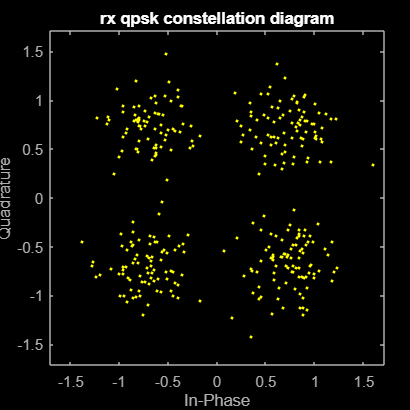

rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);

if counter==nLoops
    figure;
    scatterplot(rxQPSKSymbols);
    title('rx qpsk constellation diagram');
end


% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:dataLength)')

errors = 73

errors = 56

errors = 34

errors = 24

errors = 15

errors = 5

errors = 6

errors = 1

nbiot_ber(counter)=errors/dataLength

nbiot_ber = 0.1086

nbiot_ber =     0.1086    0.0833


nbiot_ber =     0.1086    0.0833    0.0506


nbiot_ber =     0.1086    0.0833    0.0506    0.0357


nbiot_ber =     0.1086    0.0833    0.0506    0.0357    0.0223


nbiot_ber =     0.1086    0.0833    0.0506    0.0357    0.0223    0.0074


nbiot_ber =     0.1086    0.0833    0.0506    0.0357    0.0223    0.0074    0.0089


nbiot_ber =     0.1086    0.0833    0.0506    0.0357    0.0223    0.0074    0.0089    0.0015



symbolRate=samplingRate/SPS

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

bitRate =  2*12*symbolRate

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

EbN0_sim(counter)=SNR*samplingRate/bitRate

EbN0_sim = 6.5000

EbN0_sim =     6.5000    7.0000


EbN0_sim =     6.5000    7.0000    7.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000



SNR_linear = 10^(SNR / 10);
Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

Eb_N0 = 9.9763

Eb_N0 =     9.9763   12.5594


Eb_N0 =     9.9763   12.5594   15.8114


Eb_N0 =     9.9763   12.5594   15.8114   19.9054


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479   39.7164


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479   39.7164   50.0000


end

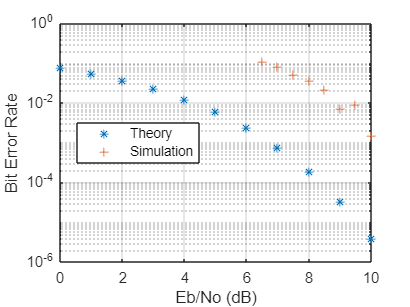

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on